# Exercice 11 - Optimisation multi-objectifs 

## Données

Un dispatcher d'énergies dispose de 5  centrales thermiques de différentes technologiques qui produisent de l'électricité. Il est capable de prédire le coût de chaque centrale à partir d'une relation de type : 


$$C_I \left(P_I \right)=a_I {\left(P_I \right)}^2 +b_I {\left(P_I \right)} +c_I$$


$C_I$ est le coût de production selon la puissance produite ($P_I$) pour l'unité *I*. 

Chaque centrale a des limites de production : $P_{I,\min } {\le P}_I \le P_{I,\max }$

Chaque centrale produit des émissions polluantes. Le dispatcher dispose de relation pour estimer la quantité totale ($T_I$) de polluants produite en kg/j par chaque centrale en fonction de sa puissance thermique ($P_I$) :  


$$T_I \left(P_I \right)=d_I {\left(P_I \right)}^2 +e_I {\left(P_I \right)} +f_I$$


Les données des 5 centrales sont disponibles dans le fichier `data_Exercice11.mat` (`load data_Exercice11`): coefficients `A, B, C, D, E` et `F` des deux formules ci-dessus ainsi que `Pmin` et `Pmax`. 

Toutes les puissances sont exprimées en MW.

clear 

load data_Exercice11

## Partie 1

La variable considérée est P, une matrice N*1 telle que : 

P = [P1 ; P2 ; ... ; PN] 

avec : 

- Pi la puissance soutirée à la centrale i 

- N = 5 

%Longueur du vecteur P 
N = length(A) ;  

%On crée un vecteur "Demandes" contenant dix valeurs différentes de la demande comprises entre Pmin et Pmax. 
Demandes = linspace(sum(Pmin),sum(Pmax),10) ; 

%On ajoute une 11e valeur au vecteur demande. Cette valeur de la demande
%servira pour les parties 2 et 3.
Demande_part2 = 400 ; 
Demandes = [Demandes, Demande_part2 ] ; 
Dlength = length(Demandes);

%Création du vecteur qui contiendra les coûts optimaux en fonction de la demande
Couts_opti = zeros(1,Dlength) ; 

%Création de la matrice qui contiendra les puissances de chaque centrale en fonction de la demande
Puissances = zeros(N,Dlength) ; 

%Démarrage de la boucle qui calcule l'optimum de la fonction coût pour
%chaque valeur de la demande
for k= 1:Dlength

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.180e+02    5.494e+02
    1      12    2.002054e+05    2.062e+02    3.439e+02    4.001e+01
    2      18    1.339785e+05    1.

Solution trouvée (en MW) :


   28.0000
   90.0000
   68.0000
   76.0000
   19.0000



Valeur de la fonction à la solution trouvée (en €) : 


   8.4038e+04



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.383e+02    5.494e+02
    1      12    2.042081e+05    1.311e+02    3.442e+02    3.856e+01
    2      18    1.992639e+05    1.

Solution trouvée (en MW) :


   73.6667
   90.0000
   68.0000
   76.0000
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   1.0927e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    5.867e+01    5.494e+02
    1      12    2.080129e+05    5.568e+01    3.444e+02    3.728e+01
    2      18    2.069847e+05    5.

Solution trouvée (en MW) :


  119.0253
   90.0000
   88.7163
   89.5917
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   1.5911e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.100e+01    5.494e+02
    1      12    2.116336e+05    1.996e+01    3.446e+02    3.616e+01
    2      18    2.115474e+05    1.

Solution trouvée (en MW) :


  144.1575
  107.0216
  107.3327
  108.4881
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   2.2371e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.007e+02    5.494e+02
    1      12    2.150828e+05    9.583e+01    3.448e+02    3.518e+01
    2      18    2.154670e+05    9.

Solution trouvée (en MW) :


  168.7965
  125.2727
  125.5838
  127.0137
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   3.0010e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    1.803e+02    5.494e+02
    1      12    2.183720e+05    1.719e+02    3.448e+02    3.434e+01
    2      18    2.190725e+05    1.

Solution trouvée (en MW) :


  193.4355
  143.5238
  143.8349
  145.5392
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   3.8827e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    2.600e+02    5.494e+02
    1      12    2.215117e+05    2.482e+02    3.448e+02    3.362e+01
    2      18    2.224661e+05    2.

Solution trouvée (en MW) :


  206.0000
  165.7796
  166.0907
  168.1297
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   4.8885e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    3.397e+02    5.494e+02
    1      12    2.245116e+05    3.246e+02    3.448e+02    3.302e+01
    2      18    2.256953e+05    3.

Solution trouvée (en MW) :


  206.0000
  193.9465
  189.0000
  196.7201
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   6.0586e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.193e+02    5.494e+02
    1      12    2.273807e+05    4.012e+02    3.448e+02    3.251e+01
    2      18    2.287891e+05    3.

Solution trouvée (en MW) :


  206.0000
  233.4826
  189.0000
  236.8507
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   7.4521e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    4.990e+02    5.494e+02
    1      12    2.301270e+05    4.780e+02    3.448e+02    3.210e+01
    2      18    2.317692e+05    4.

Solution trouvée (en MW) :


  206.0000
  284.0000
  189.0000
  266.0000
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   9.1104e+05



Valeur flag de fmincon :


     1



____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([A.*P.^2+B.*P+C])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    2.328123e+05    9.900e+01    5.494e+02
    1      12    2.061105e+05    9.389e+01    3.443e+02    3.790e+01
    2      18    2.039954e+05    9.

Solution trouvée (en MW) :


  102.8442
   90.0000
   76.7303
   77.4255
   53.0000



Valeur de la fonction à la solution trouvée (en €) : 


   1.3146e+05



Valeur flag de fmincon :


     1



### **1.Définition de la fonction objectif à minimiser**

La fonction objectif à minimiser est la fonction des coûts en fonction des puissances.

f_obj1 = @(P) sum([A.*P.^2+B.*P+C]) ; 

### **2.Définition des contraintes**

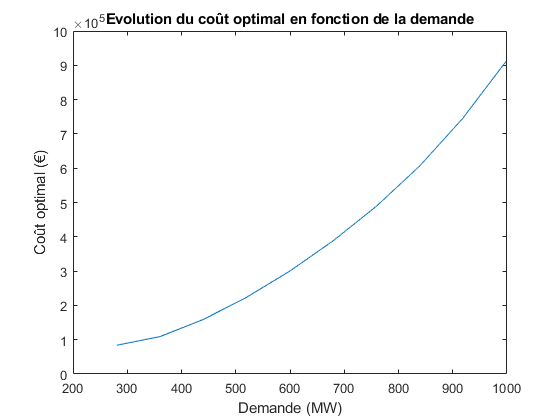

% contraintes inégalités linéaires : contenues dans les bornes

% contraintes égalités linéaires

Aeq_lin1 = ones(1,N) ;
beq_lin1 = [Demandes(k)] ;  

### 3. Définition des bornes

lb = Pmin ; 
ub = Pmax ; 

### 4. Solver : fmincon

P0 = Pmax/2 ;
options = optimoptions('fmincon','Display','iter','Diagnostics','on');
[P1,fval1,flag1,out1]= fmincon(f_obj1,P0,[],[],Aeq_lin1,beq_lin1,lb,ub,'',options);

### 5. Affichage des résultats 

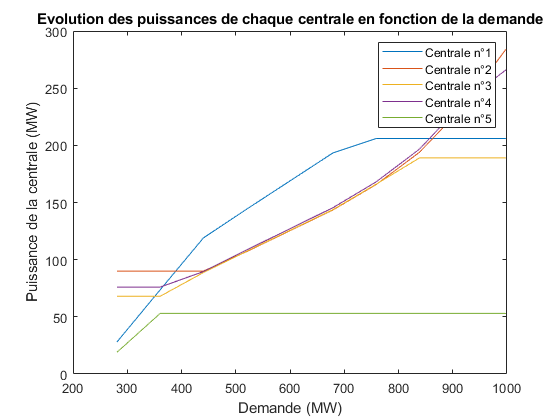

disp('Solution trouvée (en MW) :')
disp(P1)
disp('Valeur de la fonction à la solution trouvée (en €) : ')
disp(fval1)

disp('Valeur flag de fmincon :')
disp(flag1)

%On ajoute le coût optimal calculé pour la nouvelle valeur de la demande dans le vecteur Couts_opti : 
Couts_opti(k) = fval1 ; 

%On ajoute les puissances de chaque centrale calculées pour la nouvelle valeur de la demande 
% dans la matrice Puissances : 
Puissances(:,k) = P1 ; 


%Fin de la boucle
end

### **6.Tracé des courbes**

%Evolution du coût optimal en fonction de la valeur de la demande
plot(Demandes(1:Dlength-1),Couts_opti(1:end-1))
xlabel('Demande (MW)')
ylabel('Coût optimal (€)')
title('Evolution du coût optimal en fonction de la demande')
%Evolution des puissances de chaque centrale en fonction de la valeur de la demande
evolution_puissance_demande = figure;
plot(Demandes(1:Dlength-1),Puissances(:,1:end-1))
xlabel('Demande (MW)')
ylabel('Puissance de la centrale (MW)')

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)sum([D.*P.^2+E.*P+F])
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)

Constraints
Nonlinear constraints:                do not exist
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       6    6.814161e+03    9.900e+01    2.078e+01
    1      12    4.449298e+03    2.417e+01    1.738e+01    4.205e+01
    2      18    4.432529e+03    2.

title('Evolution des puissances de chaque centrale en fonction de la demande')

%Je crée la légende. Pour chaque courbe je souhaite écrire 'Centrale n°' et

Vecteur puissance permettant de minimiser la production de polluants pour une demande de 400 MW (en MW):


%que le numéro correspondant soit rempli automatiquement. Pour cela je crée une boucle. 

   71.6220
   90.0000
   68.0000
  129.7628
   40.6152



Valeur de la fonction objectif environnementale à la solution trouvée (en kg/h) : 


%num2str me permet de convertir i (dont la valeur varie de 1 à N) en chaîne

   3.6542e+03



%de caractères (changement de type).

Valeur flag de fmincon :


%cellstr me permet de stocker dans un vecteur des chaînes de caractères.

     1




for i=1:N
    cc(i)=cellstr(['Centrale n°' num2str(i)]);

Résultat d un point de vue économique si on utilise l optimum économique pour une demande de 400 MW (en €) :


end

   1.3146e+05



legend(cc)

Résultat d un point de vue économique si on utilise l optimum environnemental pour une demande de 400 MW (en €) :


## Partie 2

### **1.Définition de la fonction objectif à minimiser**

La fonction objectif à minimiser est la fonction des émissions polluantes en fonction des puissances.

%D et E sont exprimés en kg/j/MW² et kg/j/MW or F ainsi que f_obj2

   1.4868e+05



%s'expriment en kg/h. Il faut donc effectuer une conversion. 

Résultat d un point de vue environnemental si on utilise l optimum environnemental pour une demande de 400 MW (en kg/h) :


   3.6542e+03



D = D/24 ; 
E = E/24 ; 

Résultat d un point de vue environnemental si on utilise l optimum économique pour une demande de 400 MW (en kg/h) :


   4.0442e+03



f_obj2 = @(P) sum([D.*P.^2+E.*P+F]) ; 

### **2.Définition des contraintes**

% contraintes inégalités linéaires : contenues dans les bornes

Pour une demande de 400 MW, le coût le plus bas est atteint avec l optimum économique



% contraintes égalités linéaires : on a une demande de 400 MW à respecter
Aeq_lin2 = ones(1,N) ;
beq_lin2 = [Demande_part2] ;  

### 3. Définition des bornes

% Les bornes ont été définies dans la partie 1. 

Pour une demande de 400 MW, la production de polluant est moins élevée avec l optimum environnemental


### 4. Solver : fmincon

% P0 ainsi que les options ont été définis dans la partie 1.
[P2,fval2,flag2,out2]= fmincon(f_obj2,P0,[],[],Aeq_lin2,beq_lin2,lb,ub,'',options);

### 5. Affichage des résultats 

disp('Vecteur puissance permettant de minimiser la production de polluants pour une demande de 400 MW (en MW):')
disp(P2)
disp('Valeur de la fonction objectif environnementale à la solution trouvée (en kg/h) : ')
disp(fval2)
disp('Valeur flag de fmincon :')
disp(flag2)

### 6. Comparaison des résultats

disp('Résultat d un point de vue économique si on utilise l optimum économique pour une demande de 400 MW (en €) :')
disp(Couts_opti(end))
disp('Résultat d un point de vue économique si on utilise l optimum environnemental pour une demande de 400 MW (en €) :')
disp(f_obj1(P2))
disp('Résultat d un point de vue environnemental si on utilise l optimum environnemental pour une demande de 400 MW (en kg/h) :')
disp(fval2)

disp('Résultat d un point de vue environnemental si on utilise l optimum économique pour une demande de 400 MW (en kg/h) :')
disp(f_obj2(Puissances(:,end)))
if Couts_opti(end) > f_obj1(P2)
    disp('Pour une demande de 400 MW, le coût le plus bas est atteint avec l optimum environnemental')
else if Couts_opti(end) < f_obj1(P2)
        disp('Pour une demande de 400 MW, le coût le plus bas est atteint avec l optimum économique')
else
    disp('Pour une demande de 400 MW, les coûts sont les mêmes en utilisant l optimum économique et environnemental')
    end
end
%Mais est-ce que les contraintes sont respectées avec l'optimum

____________________________________________________________
   Diagnostic Information

Number of variables: 5

Functions 
Objective:                            @(P)fobj(P)
Gradient:                             finite-differencing
Hessian:                              finite-differencing (or Quasi-Newton)
Nonlinear constraints:                @(P)contraintes_NL(P,D,E,F)
Nonlinear constraints gradient:       finite-differencing

Constraints
Number of nonlinear inequality constraints: 5
Number of nonlinear equality constraints:   0
 
Number of linear inequality constraints:    0
Number of linear equality constraints:      1
Number of lower bound constraints:          5
Number of upper bound constraints:          5

Algorithm selected
   interior-point


____________________________________________________________
   End diagnostic information
                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0    

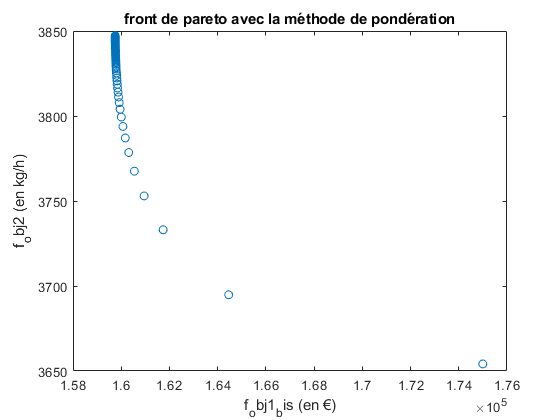

%environnemental ? 
if fval2 > f_obj2(Puissances(:,end))
    disp('Pour une demande de 400 MW, la production de polluant est moins élevée avec l optimum économique')
else if fval2 < f_obj2(Puissances(:,end))
        disp('Pour une demande de 400 MW, la production de polluant est moins élevée avec l optimum environnemental')

else
    disp('Pour une demande de 400 MW, la production de polluants est la même en utilisant l optimum économique et environnemental')
    end
end

## Partie 3 : Méthode des pondérations

%On crée un vecteur contenant dix coefficients de pondération
vecteur_coeffs_ponderation=linspace(0,1,100);

%On crée un vecteur qui contiendra les vecteurs de puissances solution pour
%chaque coeff de pondération utilisé
Psol=zeros(N,length(vecteur_coeffs_ponderation));

%On crée un vecteur qui contiendra les évaluations des fonctions objectifs
%pour les puissances solution
fsol=zeros(2,length(vecteur_coeffs_ponderation));

%Taxe environnementale en €/(kg/h) (on fait la moyenne de 0,5€ et 0,1€ et
%on convertit les jours en heure)
taxe_env = ((0.5+0.1)/2)*24 ; 

%Nouvelle fonction objectif n°1 (fonction économique) comprenant également les coûts liés à la


Solver stopped prematurely.

fgoalattain stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 6.000000e+02.


Local minimum possible. Constraints satisfied.

fgoalattain stopped because the size of the current search direction is less than
twice the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<

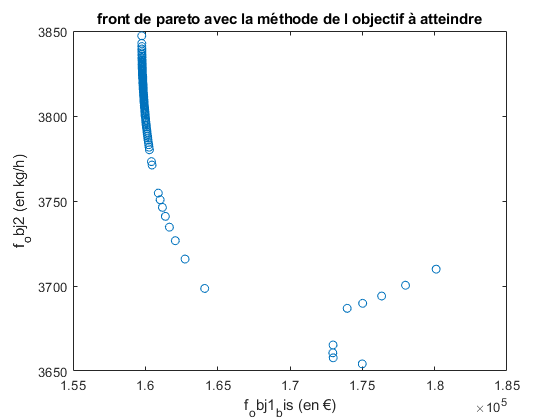

%taxe environnementale 

f_obj1_bis = @(P) sum([A.*P.^2+B.*P+C]) + sum([D.*P.^2+E.*P+F])*taxe_env ; 

%Contraintes linéaires ingéalité comprises dans les bornes

%Contrainte linéaires égalité : les mêmes que dans la partie 2
%Contraintes non-linéaires : sous-fonction en fin de code

for i=1:length(vecteur_coeffs_ponderation)

Valeur minimale de la fonction économique en utilisant la méthode de pondération (en €)


    coeff_ponderation=vecteur_coeffs_ponderation(i);

   1.5975e+05



    fobj = @(P) coeff_ponderation*f_obj1_bis(P) + (1-coeff_ponderation)*f_obj2(P);

Valeur minimale de la fonction environnementale en utilisant la méthode de pondération (en kg/h)


    [P3,fval3,flag3,out3]=fmincon(@(P) fobj(P),P0,[],[],Aeq_lin2,beq_lin2,lb,ub,@(P) contraintes_NL(P,D,E,F),options);

   3.6542e+03



    Psol(:,i)=P3;

Valeur minimale de la fonction économique en utilisant la méthode de l objectif à atteindre (en €)


    fsol(:,i)=[f_obj1_bis(P3) ; f_obj2(P3)] ;

   1.5975e+05



end

Valeur minimale de la fonction économique en utilisant la méthode de l objectif à atteindre (en kg/h)


% Tracé Pareto

   3.6542e+03



plot(fsol(1,:),fsol(2,:),'O')
title('front de pareto avec la méthode de pondération') ; 
xlabel('f_obj1_bis (en €)') ; 
ylabel('f_obj2 (en kg/h)') ; 

## Partie 3 : Méthode du but à atteindre 

%On crée un vecteur qui contient les différents poids que l'on va utiliser
vecteur_poids=linspace(0,1,100);

%On crée un vecteur qui contiendra les vecteurs de puissances solution pour
%chaque poids utilisé
Psol_bis=zeros(N,length(vecteur_poids));

%On crée un vecteur qui contiendra les évaluations des fonctions objectifs
%pour les puissances solution
fsol_bis=zeros(2,length(vecteur_poids));

for j=1:length(vecteur_poids)
    poids=vecteur_poids(j);
    fun = @(P) [ f_obj1_bis(P) ; f_obj2(P)] ; 
    goal = [min(fsol(1,:)),min(fsol(2,:))] ; 
    weight = [poids,1-poids] ; 
    [P4, fval4, factor4,flag4,output4] = fgoalattain(fun,P0,goal,weight,[],[],Aeq_lin2,beq_lin2,lb,ub,@(P) contraintes_NL(P,D,E,F)) ;
    Psol_bis(:,j)=P4;
    fsol_bis(:,j)=[f_obj1_bis(P4) ; f_obj2(P4)] ;
end
% Tracé Pareto
plot(fsol_bis(1,:),fsol_bis(2,:),'O')
title('front de pareto avec la méthode de l objectif à atteindre') ; 
xlabel('f_obj1_bis (en €)') ; 
ylabel('f_obj2 (en kg/h)') ; 

## Conclusions

A partir de l'ensemble des résultats obtenus, quelles sont vos conclusions générales sur l'optimum de fonctionnement ?  

disp('Valeur minimale de la fonction économique en utilisant la méthode de pondération (en €)')
disp(min(fsol(1,:)))
disp('Valeur minimale de la fonction environnementale en utilisant la méthode de pondération (en kg/h)')
disp(min(fsol(2,:)))
disp('Valeur minimale de la fonction économique en utilisant la méthode de l objectif à atteindre (en €)')
disp(min(fsol_bis(1,:)))
disp('Valeur minimale de la fonction économique en utilisant la méthode de l objectif à atteindre (en kg/h)')
disp(min(fsol_bis(2,:)))

On constate que les deux méthodes renvoient le même minimum, il doit donc s'agir du minimum locale. 

## Partie 3 : Fonction des contraintes non linéaires

function [cineq,ceq] = contraintes_NL(P,D,E,F)

%Une penalite financière importante est appliquée si on dépasse un flux de production de polluants 
% compris entre 90000 et 95000 kg/j. La production de polluants T ne doit donc pas dépasser cette limite. 

flux_limite = ((90000+95000)/2)/24 ; %on fait la moyenne de 90 000 et 95 000 et on convertit en kg/h

cineq = D.*P.^2+E.*P+F - flux_limite ;  
ceq = []; 
end